# Plot States

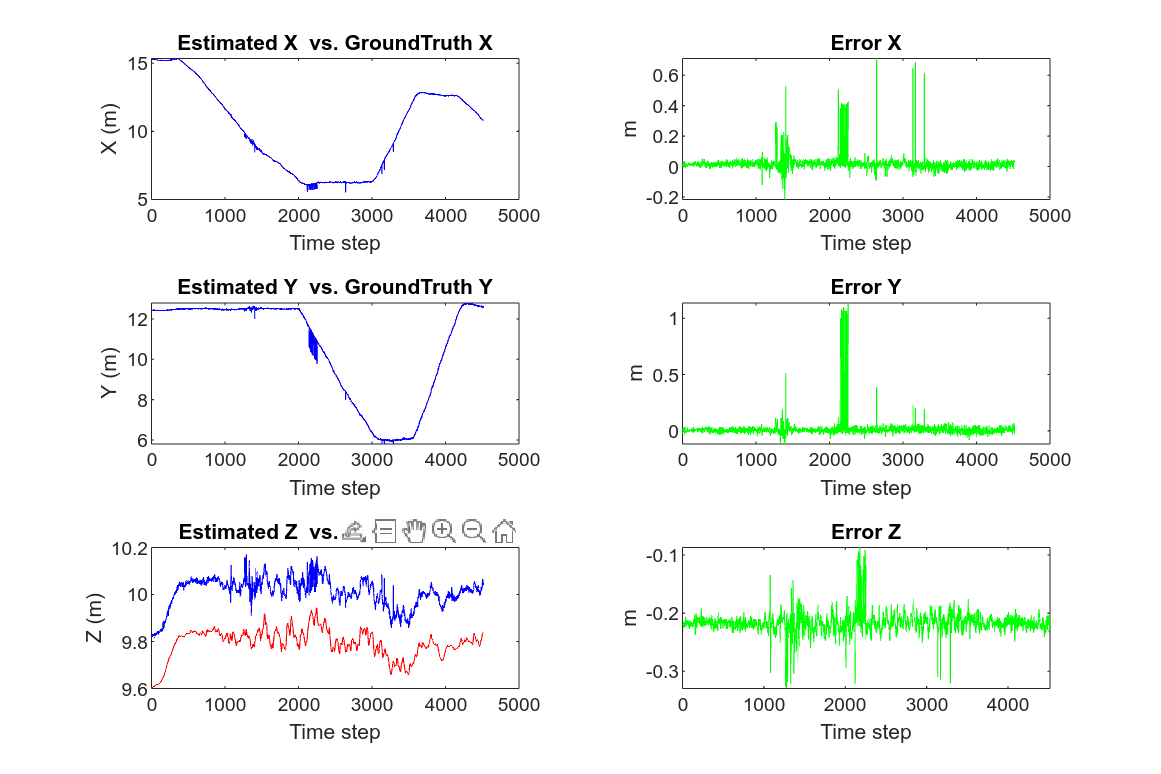

clear;clc;close;

% Data
filename_1 = "/home/leo/mts/src/coverage/record/uav3.csv";
% filename_2 = "/home/leo/plan/src/fw_control/data/EmEstimation/PoseTruth.csv";
M_1 = readmatrix(filename_1);
% M_2 = readmatrix(filename_2);

% Variable
counter = size(M_1);

groundTruth = M_1(:,13:15);
estimation = M_1(:,16:18);

begin = 2;
end_ = 4517;

ErrorX = groundTruth(begin:end_,1) - estimation(begin:end_,1);
ErrorY = groundTruth(begin:end_,2) - estimation(begin:end_,2);
ErrorZ = groundTruth(begin:end_,3) - estimation(begin:end_,3);

RMSX = sqrt(sum(ErrorX(:,1).^2)/(counter(1)-1));
RMSY = sqrt(sum(ErrorY(:,1).^2)/(counter(1)-1));
RMSZ = sqrt(sum(ErrorZ(:,1).^2)/(counter(1)-1));

for i = begin:end_


    hold on;

    t = tiledlayout(3, 2, 'TileSpacing','loose');

    % X - axis
    nexttile;
    % subplot(3,2,1);
    % plot(begin-1970:1:i-1970, groundTruth(begin:i,1), "r", begin-1970:1:i-1970, estimation(begin:i,1), "b");
    plot(begin-1:1:i-1, groundTruth(begin:i,1), "r", begin-1:1:i-1, estimation(begin:i,1), "b");
    title('Estimated X  vs. GroundTruth X');
    xlabel("Time step"); ylabel("X (m)");

    hold on;

    % X - Error
    % subplot(3,2,2);
    nexttile;
    % plot(begin-1970:1:i-1970, groundTruth(begin:i,1) - estimation(begin:i,1), "g");
    plot(begin-1:1:i-1, groundTruth(begin:i,1) - estimation(begin:i,1), "g");
    title('Error X');
    xlabel("Time step"); ylabel("m");

    hold on;

    % Y - axis
    % subplot(3,2,3);
    nexttile;
    % plot(begin-1970:1:i-1970, groundTruth(begin:i,2), "r", begin-1970:1:i-1970, estimation(begin:i,2), "b");
    plot(begin-1:1:i-1, groundTruth(begin:i,2), "r", begin-1:1:i-1, estimation(begin:i,2), "b");
    title('Estimated Y  vs. GroundTruth Y');
    xlabel("Time step"); ylabel("Y (m)");

    hold on;

    % Y - Error
    % subplot(3,2,4);
    nexttile;
    % plot(begin-1970:1:i-1970, groundTruth(begin:i,2) - estimation(begin:i,2), "g");
    plot(begin-1:1:i-1, groundTruth(begin:i,2) - estimation(begin:i,2), "g");
    title('Error Y');
    xlabel("Time step"); ylabel("m");

    hold on;

    % Z - axis
    % subplot(3,2,5);
    nexttile;
    % plot(begin-1970:1:i-1970, groundTruth(begin:i,3), "r", begin-1970:1:i-1970, estimation(begin:i,3), "b");
    plot(begin-1:1:i-1, groundTruth(begin:i,3), "r", begin-1:1:i-1, estimation(begin:i,3), "b");
    title('Estimated Z  vs. GroundTruth Z');
    xlabel("Time step"); ylabel("Z (m)");
    % ylim([0 11]);

    hold on;

    % Z - Error
    % subplot(3,2,6);
    nexttile;
    % plot(begin-1970:1:i-1970, groundTruth(begin:i,3) - estimation(begin:i,3), "g");
    plot(begin-1:1:i-1, groundTruth(begin:i,3) - estimation(begin:i,3), "g");
    title('Error Z');
    xlabel("Time step"); ylabel("m");

    hold on;

    % Configuration of Figure
    xlim([0 i-1]);
    drawnow;
    pause(1/1000);

    hold off;

    % if i < 100
    % 
    %     clf;
    % end

    % tiledlayout('flow');
    set(gcf,'units','points','position',[0,0,1080,720]);

end